### Plotting Fig.S4a,b

### 2-dimensional MQC spectrum of the dipolar-ordered states, produced by the Free evolution (a), and the Floquet evolution (b), respectively

Code last modified by Yuchen Li, 2023-10-12

clc;clear

#### For case of  Free evolution

load S_FreeEvolution.mat
mean_noise_std=7.1*1e-4; %Approximated value of the standard error of the noise, estimated from the FID.

L=8;
fft_alpha=fftshift(fft(S,L,2)/L,2);
RealPart_2D=real(fftshift(fft(fft_alpha,L,1)/L,1));

ZeroOrder=RealPart_2D(L/2+1,L/2+1)

ZeroOrder = 0.2467

DoubleOrder=RealPart_2D(L/2+1,L/2-1)

DoubleOrder = 0.3710

Raio=DoubleOrder/ZeroOrder

Raio = 1.5038

var_Zero=mean_noise_std^2/L^2;
std_zero=var_Zero.^0.5

std_zero = 8.8750e-05

var_other=mean_noise_std^2/(2*L^2);
std_other=var_other.^0.5

std_other = 6.2756e-05

Ratio_std=sqrt(var_other./(ZeroOrder.^2)+var_Zero*(DoubleOrder.^2)./(ZeroOrder.^4)) 

Ratio_std = 5.9778e-04

Ratio_uncertainty=1.96*Ratio_std

Ratio_uncertainty = 0.0012


delta=360/L;

figure()
T=L*delta/360*2*pi;
delta_f=2*pi/T;
x1=(-L/2:L/2-1)*delta_f;
x2=(-L/2:L/2-1)*delta_f;
y=RealPart_2D

y =     0.0002    0.0000    0.0000   -0.0000   -0.0003   -0.0000    0.0000    0.0000
    0.0001    0.0001   -0.0001    0.0000   -0.0001   -0.0000   -0.0000   -0.0001
   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000    0.0000    0.0001   -0.0000
    0.0000    0.0001    0.0001    0.0002   -0.0001    0.0001    0.0001   -0.0000
    0.0002    0.0002    0.3710    0.0052    0.2467    0.0052    0.3710    0.0002
    0.0000   -0.0000    0.0001    0.0001   -0.0001    0.0002    0.0001    0.0001
   -0.0001   -0.0000    0.0001    0.0000   -0.0000   -0.0000   -0.0001   -0.0001
    0.0001   -0.0001   -0.0000   -0.0000   -0.0001    0.0000   -0.0001    0.0001


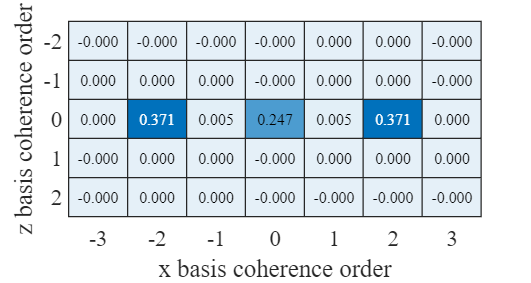

h=heatmap(x1,x2,y);
colorbar off
xlabel('x basis coherence order')
ylabel('z basis coherence order')
xlim([-3,3])
ylim([-2 2])
h.CellLabelFormat = '%0.3f';
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,7.5,4]);
fontsize(gcf,9,'points')

#### For case of  Floquet evolution

load S_FloquetEvolution.mat
mean_noise_std=6.9*1e-4; %Approximated value of the standard error of the noise, estimated from the FID.

L=16;
fft_alpha=fftshift(fft(S,L,2)/L,2);
RealPart_2D=real(fftshift(fft(fft_alpha,L,1)/L,1));

ZeroOrder=RealPart_2D(L/2+1,L/2+1)

ZeroOrder = 0.2472

DoubleOrder=RealPart_2D(L/2+1,L/2-1)

DoubleOrder = 0.3725

Raio=DoubleOrder/ZeroOrder

Raio = 1.5068

var_Zero=mean_noise_std^2/L^2;
std_zero=var_Zero.^0.5

std_zero = 4.3125e-05

var_other=mean_noise_std^2/(2*L^2);
std_other=var_other.^0.5

std_other = 3.0494e-05

Ratio_std=sqrt(var_other./(ZeroOrder.^2)+var_Zero*(DoubleOrder.^2)./(ZeroOrder.^4)) 

Ratio_std = 2.9040e-04

Ratio_uncertainty=1.96*Ratio_std

Ratio_uncertainty = 5.6917e-04


delta=360/L;

figure()
T=L*delta/360*2*pi;
delta_f=2*pi/T;
x1=(-L/2:L/2-1)*delta_f;
x2=(-L/2:L/2-1)*delta_f;
y=RealPart_2D

y =     0.0001   -0.0004    0.0001    0.0001   -0.0001    0.0000   -0.0000   -0.0001    0.0000   -0.0001   -0.0000    0.0000   -0.0001    0.0001    0.0001   -0.0004
   -0.0006   -0.0000    0.0002    0.0001    0.0006   -0.0001    0.0002    0.0002    0.0000    0.0001   -0.0001   -0.0002    0.0003   -0.0001    0.0002   -0.0003
    0.0006    0.0001    0.0001   -0.0001   -0.0002    0.0000   -0.0002    0.0002   -0.0001   -0.0001    0.0005   -0.0003    0.0001    0.0001   -0.0003    0.0002
   -0.0005    0.0005   -0.0002   -0.0002    0.0001    0.0002    0.0001   -0.0001    0.0000    0.0003   -0.0005   -0.0000   -0.0002   -0.0003    0.0001    0.0000
   -0.0000   -0.0005   -0.0003   -0.0001   -0.0000    0.0002    0.0001    0.0002    0.0001    0.0003   -0.0005   -0.0006   -0.0002   -0.0003    0.0005    0.0005
    0.0003    0.0005    0.0002   -0.0001    0.0000   -0.0001   -0.0001   -0.0001   -0.0007   -0.0002    0.0001   -0.0002   -0.0001    0.0001   -0.0002    0.0002
    0.0001   -0.0002    0.0003

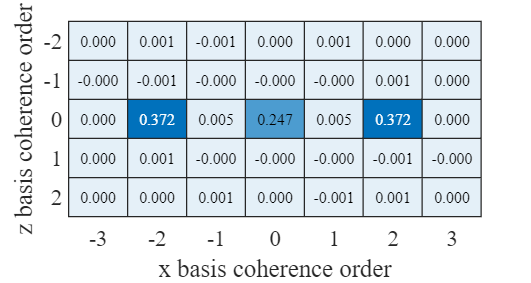

h=heatmap(x1,x2,y);
colorbar off
xlabel('x basis coherence order')
ylabel('z basis coherence order')
xlim([-3,3])
ylim([-2 2])
h.CellLabelFormat = '%0.3f';
fontname(gcf,"Times New Roman")
set(gcf,'unit','centimeters','position',[10,10,7.5,4]);
fontsize(gcf,9,'points')